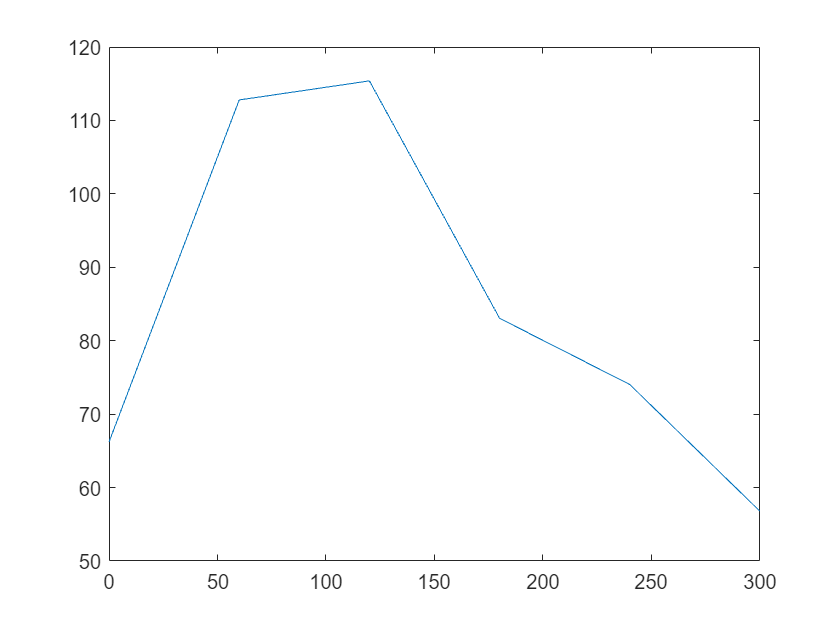

data = zeros(1,360);
interval = 60;
data = simulated_response_curve(interval).data;
ang = 0:interval:359;
plot(ang,data)

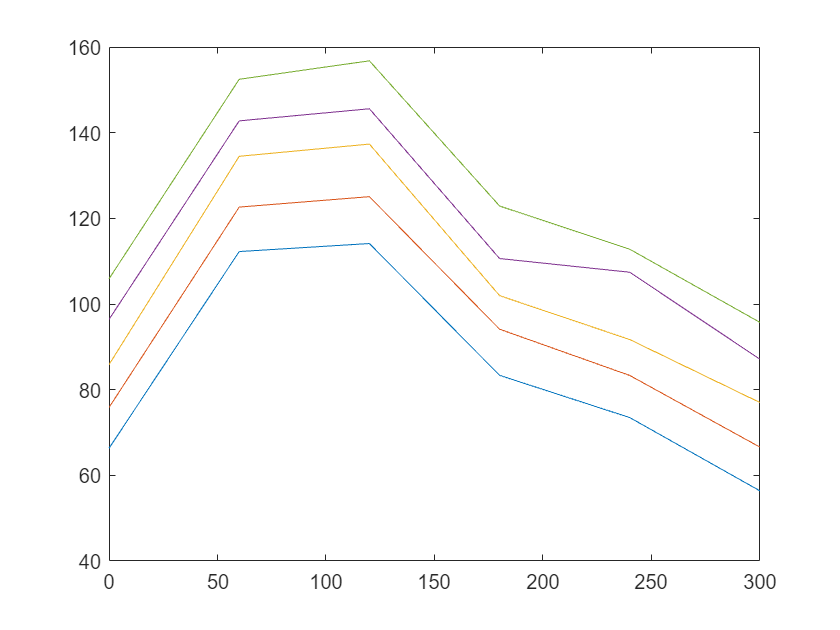

data = repmat(data,5,1) + randn(5,360/interval);
plot(ang,data(1,:),ang,data(2,:)+10,ang,data(3,:)+20,ang,data(4,:)+30,ang,data(5,:)+40),

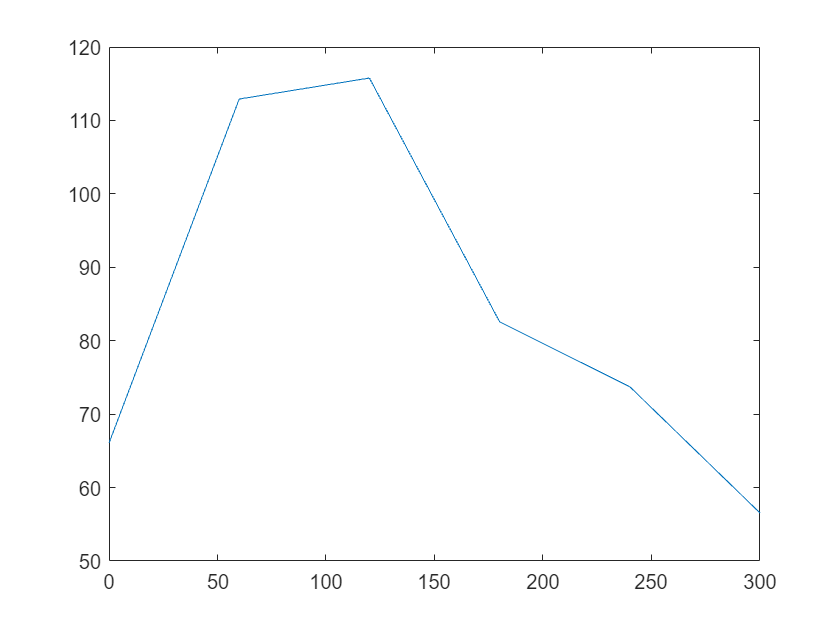

data1 = mean(data,1);
plot(ang,data1),

 lik = bayes_grid_function(data,interval).lik;
lik = lik/sum(lik,'all');
[M,I] = max(lik,[],'all'); % get maximum liklihood of parameters value and get the index of parameters
[i,j,k,h] = ind2sub(size(lik),I);


p_rp =sum(sum(sum(lik,4),3),2);
p_rp = p_rp/sum(p_rp);
p_ang = squeeze(sum(sum(sum(lik,4),3),1));
p_ang = p_ang/sum(p_ang);
p_rn = squeeze(sum(sum(sum(lik,4),2),1)); 
p_rn = p_rn/sum(p_rn);
p_sig = squeeze(sum(sum(sum(lik,3),2),1));
p_sig = p_sig/sum(p_sig);

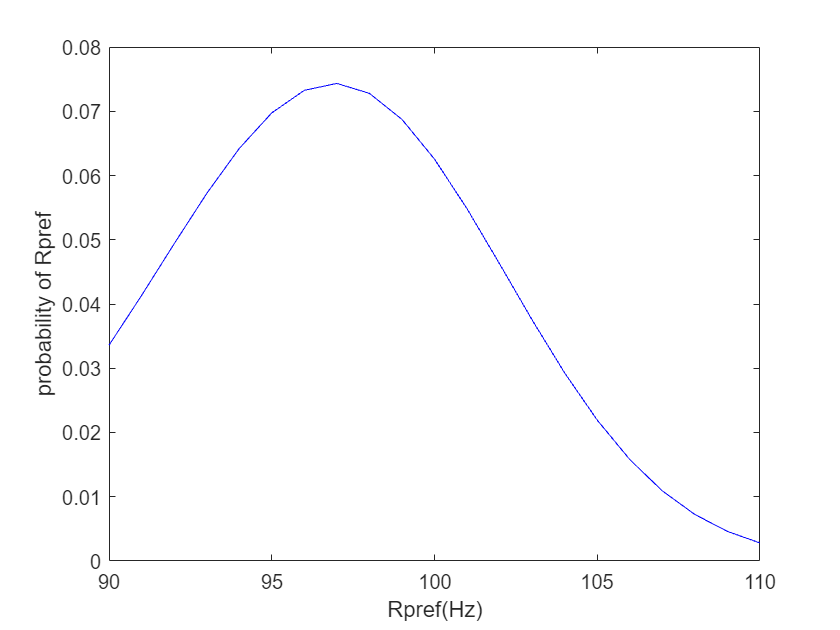

plot((85:155)-20,p_rp,'b'),% Rp - offset = 120-20 = 100
xlabel("Rpref(Hz)"), 
ylabel("probability of Rpref"),
xlim([90 110])

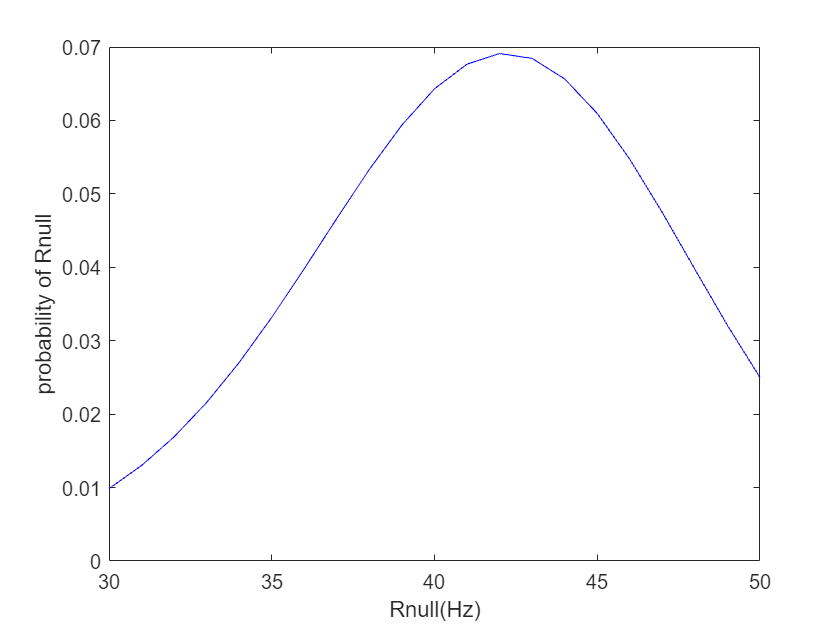


plot((25:95)-20,p_rn,'b'),% Rn - offset = 60 - 20 = 40
xlabel("Rnull(Hz)"),
ylabel("probability of Rnull"),
xlim([30 50])

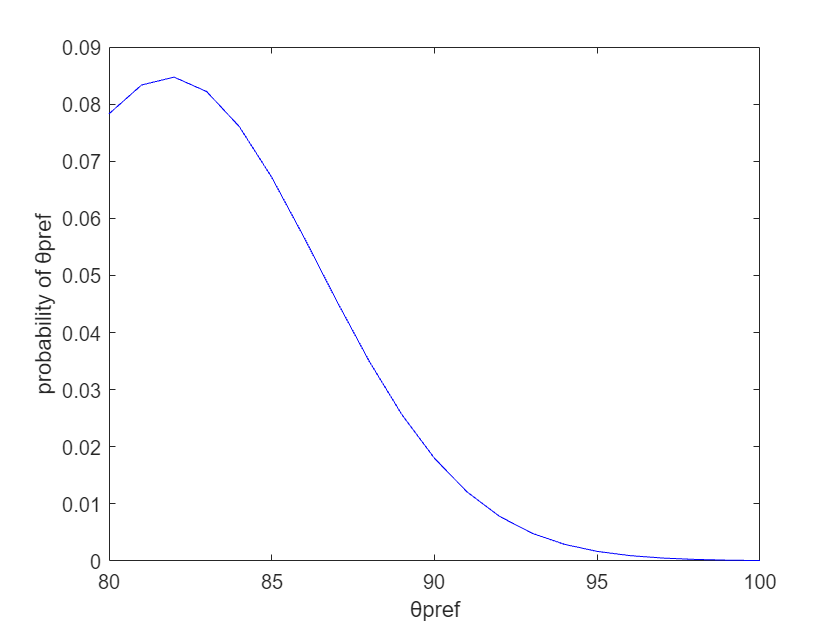


plot(0:359,p_ang,'b'),
xlabel(  "θpref"),
ylabel("probability of θpref"),
xlim([80 100])

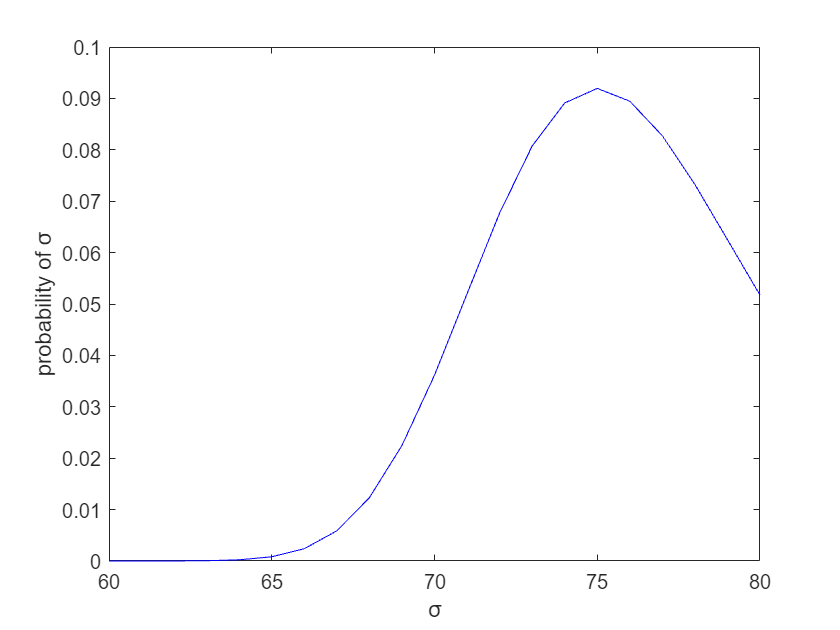


plot(40:100,p_sig,'b'),
xlabel("σ"),
ylabel("probability of σ"),
xlim([60 80])